
%Single Molecule Behavior Simulator based on Monte-Carlo Simulations on low
%irradiance trends collected on a CCD/CMOS camera with accquisition times
%much slower than radiative and non radiative decay.
% The unit time (or time step) in this simulation is longer than
% fluorescence lifetime, but shorter than dark-state lifetime. Therefore,
% it can be assumed that the molecule must stay or retun to S0 or D in each
% unit time cycle.
%Authors: Srijit Mukherjee and Sheng-Ting Hung

clc; clear; cla; 
% % Number of trajectories
nSim = 500; 
sumton=zeros(nSim);
sumtoff=zeros(nSim);
savetraj=zeros(500,nSim);
for nnn=1:nSim


% Ensemble parameters for a the FP of interest: Tip Use SI
h = 6.626*10^-34; c_light = 2.998*10^8; NA = 6.022E23; % constants
lambda = 561*10^-9; % Excitation wavelength in m
I0 = 1.24e4; % Laser Intensity in W/m^2 (W/cm^2 = 1e4 W/m^2)
epsilon = 71E3; % Molar exctinction coefficient in M^-1cm^-1 at lambda;
sigma = 2.303*epsilon*1E3*1E-4/NA; % Absorption cross-section in m^2
kEx = (I0*sigma*lambda)/(h*c_light); % Excitation rate, in Hz
QY = 0.22; % Quanutm yield
tau = 1.78e-9; % Excited state lifetime in sec
tGSR=3.76; % D to S0 time in seconds
tDSC=1/(171509); % S1 to D time in Seconds
kEm = QY/tau; % Radiative emission rate constant, in Hz
kDSC = 1/tDSC; % DSC rate constant, in Hz
kGSR = 1/tGSR; % GSR rate constant, in Hz
kIC = (1/tau)-kEm; % Non radiative decay rate constant, in Hz


%Time step data
unitT = 1e-6; % Unit time of the simulation in sec now I am considering each time unit is 10us
NunitT = 1.5e8; % Total number of timesteps you are running the simulation for
% At each time step 
Sig = zeros(NunitT,1); % Possible fluorescence at each time point [Sig(x,1)=0 (off) or 1 (on)]
S = zeros(NunitT,1); % Possible electronic state, 0=S0, 1=S1, 2=D, where D is dark state
TimeAxis = zeros(NunitT,1);
Sig(1) = 0; % Initial fluorescence signal
S(1) = 0; % Initial electronic state
OnCount = 0; % ON state counts


% Quick check
kON_En = kEx*kDSC/(kEm+kIC+kDSC);
tauON_En = 1/kON_En;
kON_SM = kEx*kIC*kDSC/(kEm+kIC+kDSC);
tauON_SM = 1/kON_SM;
% Parameters below are for ON/OFF time caculation

%Defining your experimental detection settings on the camera

time = unitT*NunitT; % Total time of the experiment
nFrame = 500; % Number of frames your camera will detect
tExpo = time/nFrame; % Total time/total frames will be the exposure time per frame
Ndt = round(tExpo/unitT); % Number of unitT in one tExpo [This is the number of events hidden in each frame]


%Defining variables that will be needed for the MC simulations

tExpoAxis = zeros(nFrame,1); % Time axis with respect to the frame rate
PhotonAcc = zeros(nFrame,1); % Accumulated ON/OFF counts in each frame
Status = zeros(nFrame,1); % ON/OFF status, 0=OFF, 1=ON
Switching = 1; % Just give a number
OnTime = zeros(length(Switching),1); % Continuous ON time
OffTime = zeros(length(Switching),1); % Continuous OFF time
OnAcc = zeros(length(Switching),1); % Accumulated ON counts
OffAcc = zeros(length(Switching),1); % Accumulated OFF counts
SigExpo = 0; % Total Sig in one tExpo
mm = 1; % Initial index of OnTime
nn = 1; % Initial index of OffTime

mCount = 0; % mCount defult value = 1, so mCount+1 is to prepare for next consecutive ON event
nCount = 0; % nCount defult value = 1, so nCount+1 is to prepare for next consecutive OFF event
Sw = 0; % Number of ON/OFF switching events
NoSw = 0; % Number of No switching events

Define probability ProbS is the probability of the molecule leaving state S. Prob_StoF is the probability of the molecule leaving from S to state F. emProb is the probability of radiative decay from S1 to S0.

%First order rate kinetics defining the probability to exist in a state at
%atime t
ProbS0 = 1-exp(-kEx*unitT); 
ProbS1 = 1-exp(-(kEm+kIC+kDSC)*unitT);
ProbD = 1- exp(-kGSR*unitT);

S1_Exit_Rate=kEm+kIC+kDSC; %Exit pathway from the S1 state

% Exit rates from each state define the movement of the system from a
% particular state
Prob_S0toS1 = 1; % Assume everytime a photon comes in you'll excite to S1 
Prob_S1toS0 = (kEm+kIC)/S1_Exit_Rate; % QY of recovery to GS [Should be ~ 1 - major pathway]
Prob_S1toD = kDSC/S1_Exit_Rate; % QY of DSC - [This number is tiny- minor pathway] 
emProb = kEm/S1_Exit_Rate;  % QY of Fluorescence [Part of the major pathway that is fluorescence]

Monte Carlo simulation on single molecule electronic state

%You run the iii loop for the number of steps you initially defined, so your catch details for each timestep (ms,us or ns)
%Remember Sig is the fluorescence signal at time point
%Remember S is the electronic state at the time point 

for iii=1:NunitT-1; %Time Axis is a point in time based on your stepsize 
    
    TimeAxis(iii)=(iii-1)*unitT;
    
    %S is your initial electronic state 
    if S(iii)==0; %If in the ground state
       
        if rand>ProbS0;
            Sig(iii+1)=0;
            S(iii+1)=0;
        else
           
        if rand>Prob_S1toS0;
                Sig(iii+1)=0;
                S(iii+1)=2;
            else
                S(iii+1)=0;
                if rand>emProb;
                    Sig(iii+1)=0;
                else
                    Sig(iii+1)=1;
                    OnCount=OnCount+1;
                end
            end
        end
    end
    
    if S(iii)==2;
        if rand>ProbD;
            Sig(iii+1)=0;
            S(iii+1)=2;
        else
            Sig(iii+1)=0;
            S(iii+1)=0;
        end
    end
end
TimeAxis(NunitT) = (NunitT-1)*unitT;
% save('FR_SigTest', 'Sig');

Calculate ON/OFF time

for ii=1:nFrame;
    tExpoAxis(ii) = ii*tExpo;
    SigExpo = 0;
    for jj=1:Ndt; % Signal counts in frame ii
        kk = (ii-1)*Ndt+jj;
        SigExpo = SigExpo+Sig(kk);
    end
    PhotonAcc(ii) = SigExpo; % Accumulated ON/OFF counts in each frame
        
    if SigExpo>0;
        Status(ii) = 1;
    elseif SigExpo==0;
        Status(ii) = 0;
    end
    
    if ii==1;
        if Status(ii)==1;
            mCount = mCount+1;
            OnTime(mm) = mCount*tExpo; 
            OnAcc(mm) = mCount;
        elseif Status(ii)==0;
            nCount = nCount+1;
            OffTime(nn) = nCount*tExpo;
            OffAcc(nn) = 0;
        end
    else % ii>1;
        if Status(ii)==Status(ii-1); % No ON/OFF switching
            if Status(ii)==1; % Continue ON
                mCount = mCount+1;
                OnTime(mm) = mCount*tExpo;
                OnAcc(mm) = mCount;
            elseif Status(ii)==0; % Continue OFF
                nCount = nCount+1;
                OffTime(nn) = nCount*tExpo;
                OffAcc(nn) = 0;
            end
            NoSw = NoSw+1;
        else % Switching ON/OFF
            if Status(ii)==1; % OFF to ON
                nn = nn+1;
                nCount = 0;
                mCount = mCount+1;
                OnTime(mm) = mCount*tExpo;
                OnAcc(mm) = mCount;
            elseif Status(ii)==0; % ON to OFF
                mm = mm+1;
                mCount = 0;
                nCount = nCount+1;
                OffTime(nn) = nCount*tExpo;
                OffAcc(nn) = 0;
            end
            Sw = Sw+1;
        end
    end
end

TotOnTime = sum(OnTime);
TotOffTime = sum(OffTime);
nOnTime = length(OnTime);
nOffTime = length(OffTime);


This section is to plot & fit ON/OFF time histogram, obtain the statistical (average) ON/OFF time, & histogram of photon counts

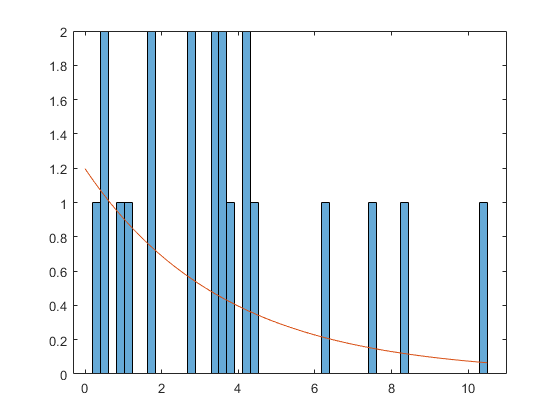

nBinsOn = 50;
nBinsOff = 50;
nBinsPhoton = 50;
% For ON time
figure(1);
HistgOn = histogram(OnTime,nBinsOn); hold on % Plot histogram

% HistgOn = histogram(OnTime,'BinWidth',0.09) % Alternative option
[HcountOn,edgesOn] = histcounts(OnTime,nBinsOn); % Get counts in each bin
FitOn = fitdist(OnTime','Exponential');
tOn = FitOn.mu;
AreaOn = sum(HcountOn*HistgOn.BinWidth);
% Plot fit curve
XvalsOn = 0:max(OnTime)/nBinsOn:max(OnTime);
FitCurveOn = AreaOn*exp(-XvalsOn/tOn)/tOn; % Compute fit curve. FitOn.mu is to get fit parameter mu.
plot(XvalsOn,FitCurveOn); hold off
% Just to check...
% hold on
% histfit(OnTime,nBinsOn,'Exponential'); hold off

% For OFF time
figure(2);
HistgOff = histogram(OffTime,nBinsOff); hold on % Plot histogram
[HcountOff,edgesOff] = histcounts(OffTime,nBinsOff); % Get counts in each bin
% HistgOff = histogram(OffTime,'BinWidth',0.09) % Alternative option
FitOff = fitdist(OffTime','Exponential');
tOff = FitOff.mu;
AreaOff = sum(HcountOff*HistgOff.BinWidth);
% Plot fit curve
XvalsOff = 0:max(OffTime)/nBinsOff:max(OffTime);
FitCurveOff = AreaOff*exp(-XvalsOff/tOff)/tOff; % Compute fit curve. FitOn.mu is to get fit parameter mu.
plot(XvalsOff,FitCurveOff); hold off
% Just to check...
% hold on
% histfit(OffTime,nBinsOff,'Exponential'); hold off

% For Photon counts
figure(3);
HistgPhoton = histogram(PhotonAcc,nBinsPhoton); hold on
[HcountPhoton,edgesPhoton] = histcounts(PhotonAcc,nBinsPhoton);
hold off

% save('FR_50ms3','OnTime','OffTime','nOnTime','nOffTime','tOn','tOff','HcountPhoton')

This section is to plot single molecule ON/OFF trace

figure(4);
stairs(tExpoAxis,PhotonAcc)% Actual ON/OFF trace observed in the experiment
savetraj(:,nnn)=PhotonAcc;
sumton(:,nnn)=tOn;
sumtoff(:,nnn)=tOff;

end



save('trajectories.txt', 'savetraj', '-ASCII','-append')

save(['DpTT_16ms' num2str(nnn) '.mat'],'OnTime','OffTime','nOnTime','nOffTime','tOn','tOff','HcountPhoton') end